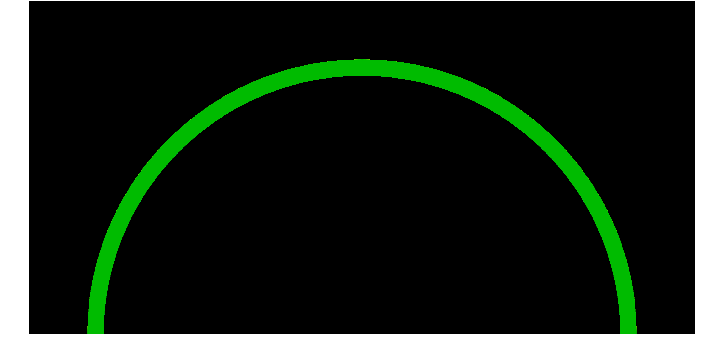

% Read the image
img = imread('rainbow.png');

% Convert the image to the HSV color space
hsv_img = rgb2hsv(img);

% Extract the hue, saturation, and value channels
hue = hsv_img(:,:,1);
saturation = hsv_img(:,:,2);
value = hsv_img(:,:,3);

% Define a range of green hue values
green_hue_low = 0.25;
green_hue_high = 0.4;

% Find all pixels with hue values in the green range
green_pixels = (hue >= green_hue_low) & (hue <= green_hue_high);

% Create a binary mask of the green pixels
green_mask = uint8(green_pixels);

% Apply the mask to the original image to extract the green color
green_img = bsxfun(@times, img, green_mask);

% Show the green image
imshow(green_img);

imshow('rainbow.png')

% read the input image
img = imread('traingle_circle.png');

% convert the image to the HSV color space
hsv_img = rgb2hsv(img);

% extract the hue channel
hue = hsv_img(:,:,1);

% create a binary mask for the green pixels in the image
green_mask = (hue >= 0.2 & hue <= 0.4);

% use morphological operations to enhance the circle
se = strel('disk', 10);
green_mask = imclose(green_mask, se);

% use regionprops to get properties of the connected components in the image
props = regionprops(green_mask, 'Area', 'Centroid');

% find the largest circle
max_area = 0;
max_circle = [];
for i = 1:numel(props)
    if props(i).Area > max_area
        max_area = props(i).Area;
        max_circle = props(i).Centroid;
    end
end

% draw a circle around the largest green object
output_img = insertShape(img, 'circle', [max_circle 50], 'LineWidth', 5, 'Color', 'blue');

% display the output image
imshow(output_img);

% v. 2.0
% v. 3.0
% Connect to the webcam.
cam = webcam(1)

cam =   webcam with properties:

                     Name: 'Integrated Camera'
     AvailableResolutions: {'1280x720'  '960x540'  '848x480'  '640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '320x180'}
               Resolution: '1280x720'
          ColorEnableMode: 'manual'
              ColorEnable: 1
                Sharpness: 3
                      Hue: 0
             WhiteBalance: 4600
             ExposureMode: 'auto'
                     Tilt: 0
                    Gamma: 120
    BacklightCompensation: 1
                     Roll: 0
                     Zoom: 100
               Saturation: 64
                 Exposure: -6
         WhiteBalanceMode: 'auto'
                 Contrast: 32
                      Pan: 0
               Brightness: 128


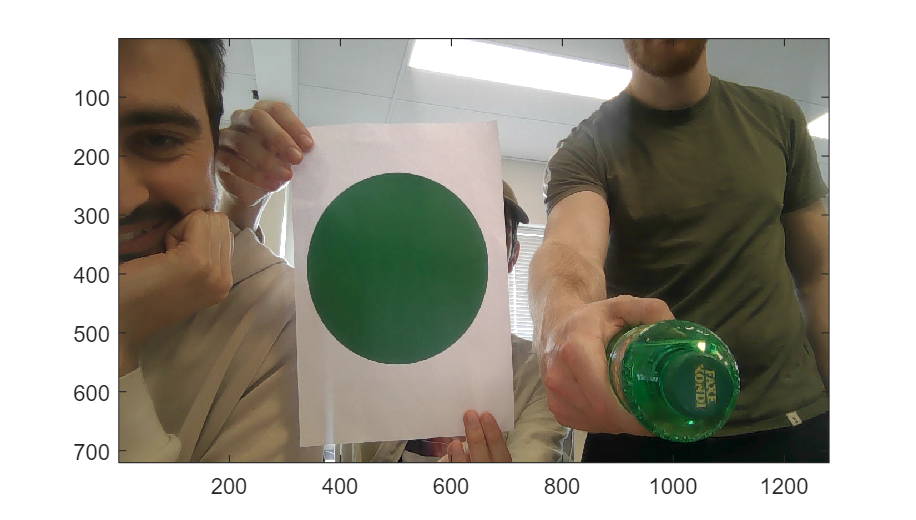


% read the input image
img = snapshot(cam);

% Display the frame in a figure window.
image(img);

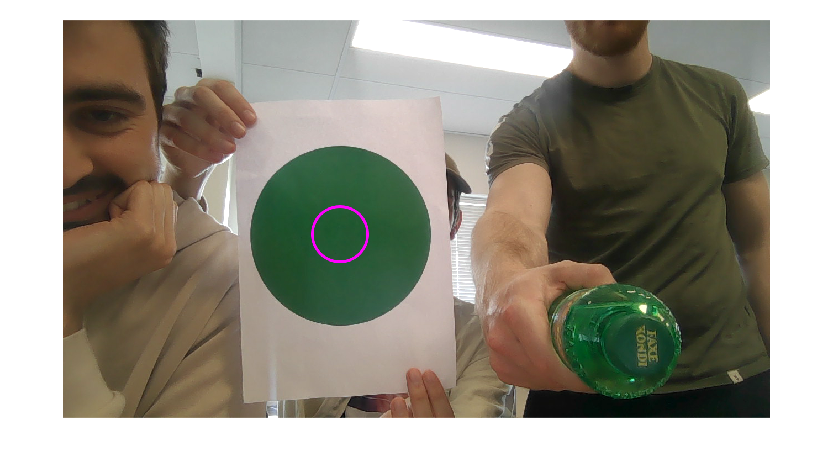


% convert the image to the HSV color space
hsv_img = rgb2hsv(img);

% extract the hue channel
hue = hsv_img(:,:,1);

% create a binary mask for the green pixels in the image
green_mask = (hue >= 0.2 & hue <= 0.4);

% use regionprops to get properties of the connected components in the image
props = regionprops(green_mask, 'Area', 'Centroid', 'Eccentricity');

% find the largest green circle
max_area = 0;
max_circle = [];
for i = 1:numel(props)
    if props(i).Area > max_area
        max_area = props(i).Area;
        max_circle = props(i).Centroid;
    end
end

% draw a circle around the largest green circle
output_img = insertShape(img, 'circle', [max_circle 50], 'LineWidth', 5, 'Color', 'magenta');

% display the output image
imshow(output_img);